Clear all outputs and inputs and load the relevant data:

close all
clear all
clc
load('BankClients.mat')

## Preparing the data

First we divide the data into numerical and categorical and prepare them accordingly.

### `Numerical data`

`By taking a rapid look at the data (with a boxplot) we can easily see that the first two columns have a much wider range than all other columns. Indeed all other columns are already within the [0,1] range.`

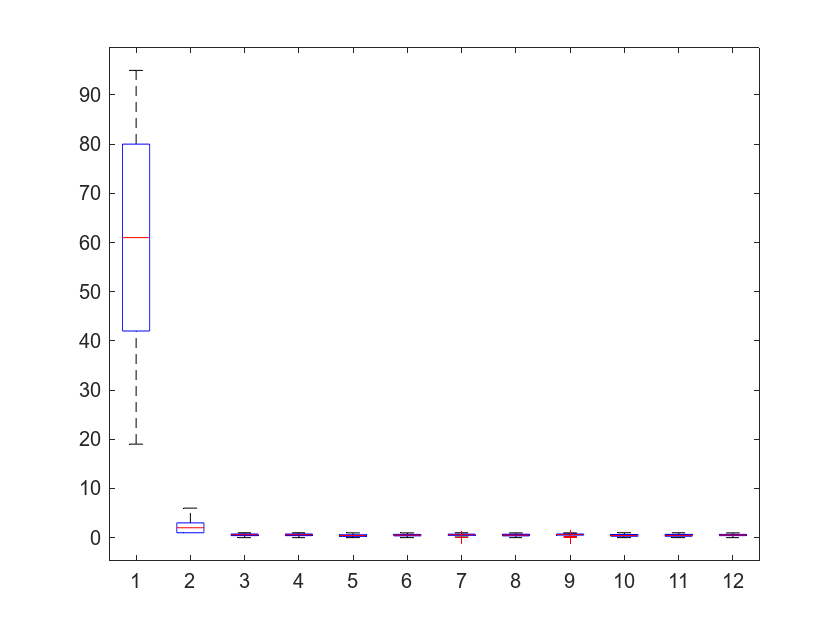

% Numerical
N = vartype('numeric');
Data = BankClients(:,2:end); % Exclude 1st col = ID
NumFeatures = Data(:,N); % subtable of numerical features
XNum = NumFeatures.Variables;
Unscaled_X_Num = NumFeatures.Variables;
boxplot(XNum) %plot all columns

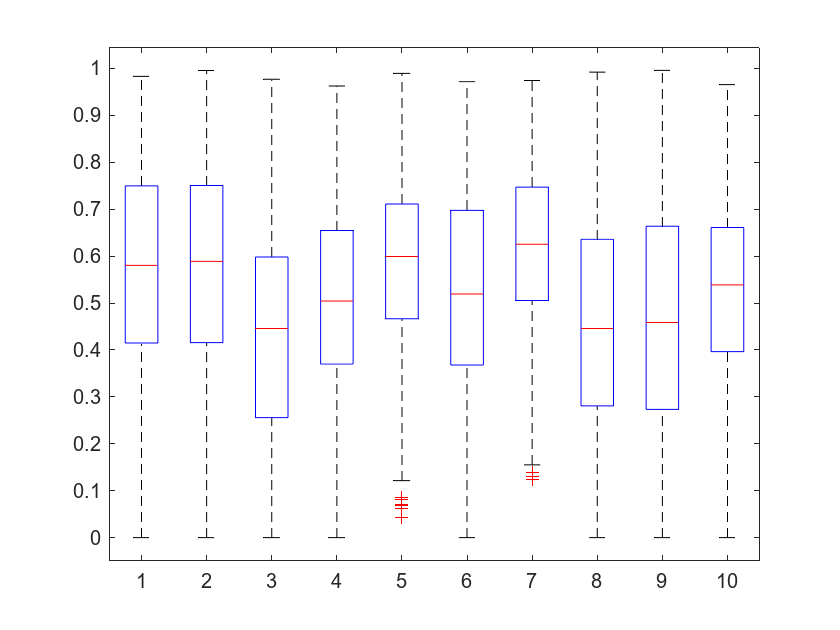

boxplot(XNum(:,3:end)) %plot only columns from the third on

`Nonetheless, to have a more equal comparison, we rescale all columns by using the zscaling algorithm:`

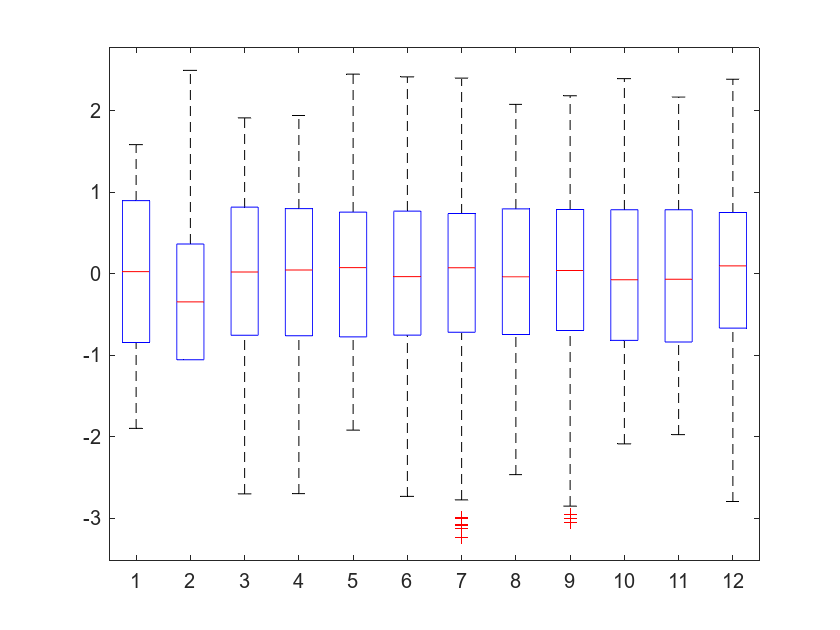

for i = 1:size(XNum,2)
    XNum(:,i) = zscore(XNum(:,i)); % normalize by zscore
end
boxplot(XNum)

### Categorical data

We create some dummy variables to deal with categorical data:

% Categorical
C = vartype('categorical');
CatFeatures = Data(:,C); % subtable of categorical features

% Encoding (ie create dummy variables)
XCat = [];
for i = 1:size(CatFeatures, 2)
    XCat_i = dummyvar(grp2idx(CatFeatures{:,i}));
    XCat = [XCat XCat_i(:,1:end-1)]; % To use the dummy variables in a model, we must delete a column
end

We put the scaled data back together and save the unscaled data for later use:

X = [XCat XNum];
Unscaled_X = [XCat Unscaled_X_Num]; 

### Dataset inspection

By inspection we can see that the dataset is composed of a lot of observations.

nObservations = size(Data,1)

nObservations = 5000

Therefore, to avoid to have our computer stuck in computational purgatory, we take a subsample:

nSubSample = 1500;
rng('default') % for reproducibility
randRows = randperm(size(X, 1), nSubSample);
X = X(randRows', :);
%we also take care to extract the same rows for the unscaled data
Unscaled_X = Unscaled_X(randRows',:);

## Unsupervised Clustering

Since we have categorical data we can't apply the usual k-means algorithm since its mathematical foundations lose meaning on categorical spaces.

### Data exploring

#### 2-D clustering

We try a few distance options. First we explore a pure numerical distance funtion, the Mahalanobis distance:

figure
%=== Mahalanobis ===%
rng('default') % for reproducibility
Y = tsne(X,'Algorithm','exact','Distance','mahalanobis');
subplot(3,2,1)
gscatter(Y(:,1),Y(:,2))
title('Mahalanobis')

Then we explore a pure numerical distance funtion, the Cityblock (or L1) distance:

%=== Cityblock ===%
rng('default') % for reproducibility
Y = tsne(X,'Algorithm','exact','Distance','cityblock');
subplot(3,2,2)
gscatter(Y(:,1),Y(:,2))
title('Cityblock')

As expected this distance doesn't give us a very good output since it is a numerical distance applied to categorical variables. We try to pass to the pure Euclidean distance:

%=== Euclidean ===%
rng('default') % for fair comparison
Y = tsne(X,'Algorithm','exact','Distance','euclidean');
subplot(3,2,3)
gscatter(Y(:,1),Y(:,2))
title('Euclidean')

Finally we also plot the values using the standardized euclidean distance:

%=== Seuclidean ===%
rng('default') % for fair comparison
Y = tsne(X,'Algorithm','exact','Distance','seuclidean');
subplot(3,2,4)
gscatter(Y(:,1),Y(:,2))
title('Seuclidean')

This is, again, a Numerical distance. We then thought it best to pass to exploring mixed distances. First we tried a mix of a Hamming distance for categorical data and Cityblock, then a combination of Hamming and Euclidean and then Hamming plus Standardized Euclidean:

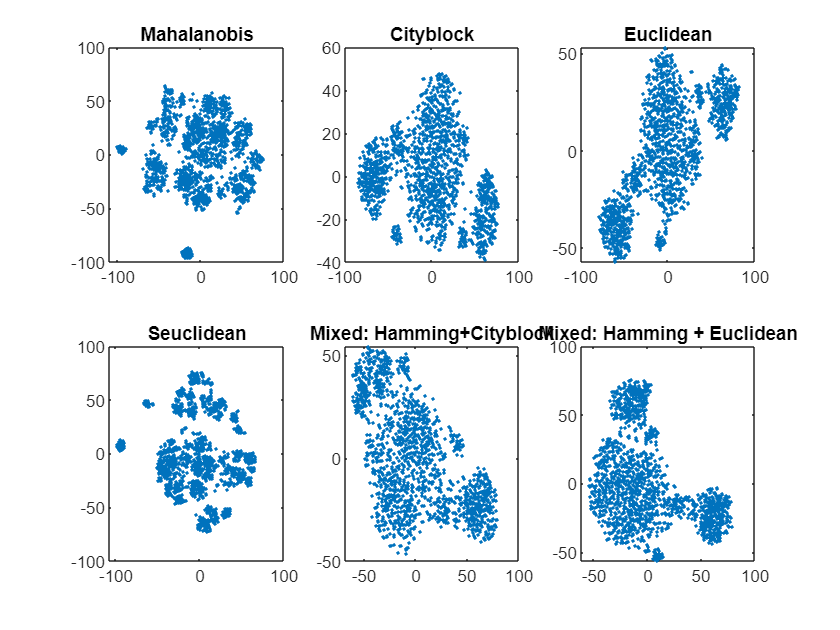

%=== Hamming + Cityblock ===%
rng('default') % for fair comparison
Y = tsne(X,'Algorithm','exact','Distance', @HammingCityblock);
subplot(3,2,5)
gscatter(Y(:,1),Y(:,2))
title('Mixed: Hamming+Cityblock')
%=== Hamming + Euclidean ===%
rng('default') % for fair comparison
Y = tsne(X,'Algorithm','exact','Distance', @HammingEuclidean);
subplot(3,2,6)
gscatter(Y(:,1),Y(:,2))
title('Mixed: Hamming + Euclidean')

We observe that the Hamming-Euclidean mixed distance seems to give us very nice cluster.

#### 3-D clustering

We also do the t-SNE plot in 3 dimensions for both mixed distances used above:

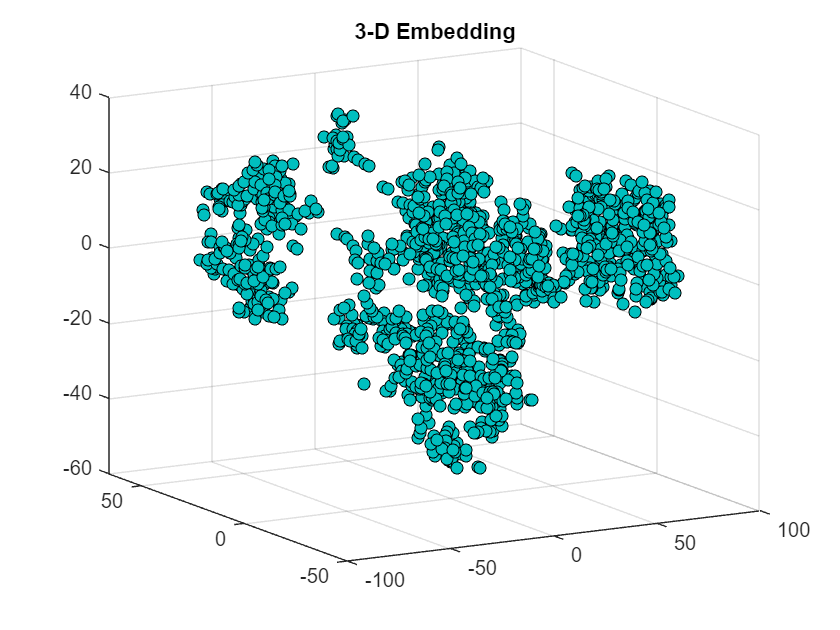

%=== 3-D Hamming+CItyblock ===%
rng('default') % for fair comparison
Y = tsne(X,'Algorithm','exact','Distance', @HammingCityblock,'NumDimensions',3);
figure
scatter3(Y(:,1),Y(:,2),Y(:,3),...
        'MarkerEdgeColor','k',...
        'MarkerFaceColor',[0 .75 .75])
title('3-D Embedding')
view(-30,15)

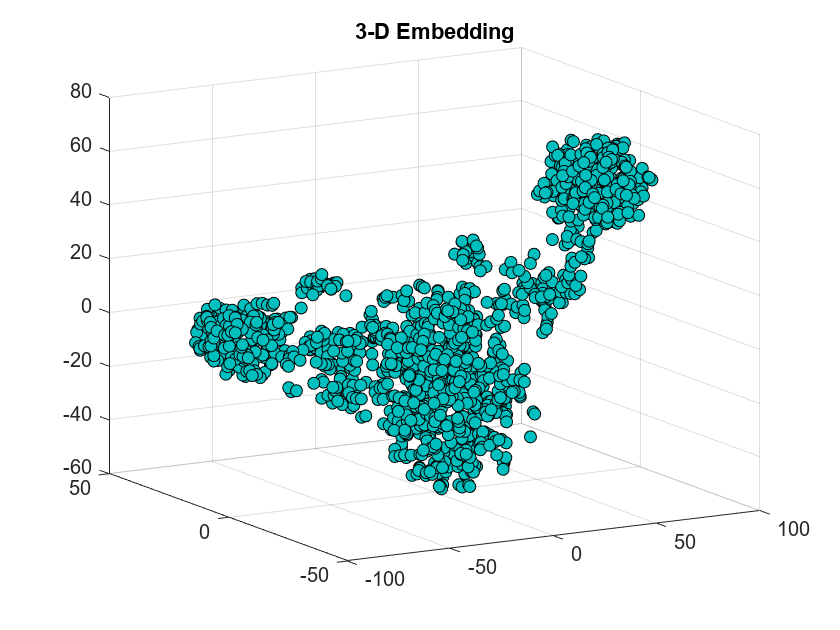

%=== 3-D Hamming+Euclidean ===%
rng('default') % for fair comparison
Y = tsne(X,'Algorithm','exact','Distance', @HammingEuclidean,'NumDimensions',3);
figure
scatter3(Y(:,1),Y(:,2),Y(:,3),...
        'MarkerEdgeColor','k',...
        'MarkerFaceColor',[0 .75 .75])
title('3-D Embedding')
view(-30,15)

As we can see the Hamming-Euclidean distance and 3 dimensions seems to be the best combination of all, in the following we use this.

### **UMAP**

To further explore the intuition gleamed in the previous visualizations we also applied the UMAP dimensionality reduction method using the euclidean distance:

UMAP & UST (v4.2), Herzenberg Lab, Stanford University,
	Original inventors: Leland McInnes, John Healy & James Melville
	MATLAB/C++/Java/Python implementors/evolvers: Connor Meehan, Jonathan Ebrahimian & Stephen Meehan


ans =

	javahandle_withcallbacks.edu.stanford.facs.swing.ImageButton

Parallelizing UMAP with MATLAB's 8 assigned logical cores for nn_descent_tasks, sgd_tasks


 Running basic (ub) reduction, v4.2
(ub=basic, us=supervised, ubt=template, ust=supervised template)


min=-11.50, max=1.50
mins:	0           0           0           0           0           0           0           0           0           0           0     -1.8994     -1.0574     -2.7039     -2.6997     -1.9205     -2.7337     -3.1323     -2.4671     -2.8337     -2.0889     -1.9759     -2.7972
maxs:	1           1           1           1           1           1           1           1           1           1           1      1.5832      2.4947      1.8667      1.9399      2.4447      2.3201      2.2168       2.066      2.1834      2.3239       2.167      2.3613
UMAP(method=MEX, n_neighbors=15, n_components=2, metric=custom, n_epochs=[], learning_rate=1, init=spectral, min_dist=0.3, spread=1, set_op_mix_ratio=1, local_connectivity=1, repulsion_strength=1, negative_sample_rate=5, transform_queue_size=4, a=0.992174408960354, b=1.11225576844318, randomize=true, target_n_neighbors=-1, target_metric='categorical', target_metric_kwds=[], target_weight=0.5, verbose=true, initial_alpha=1, sparse_d

ans =   Contour with properties:

    EdgeColor: [0.5000 0.5000 0.6000]
    LineStyle: '-'
    LineWidth: 1
    FaceColor: 'none'
    LevelList: [0.0087 0.0135 0.0174 0.0209 0.0247 0.0275 0.0291 0.0307 0.0333 0.0417]
        XData: [256×256 double]
        YData: [256×256 double]
        ZData: [256×256 double]

  Show all properties


UMAP reduction finished (cost 2.40 secs)
 Finished basic (ub) reduction


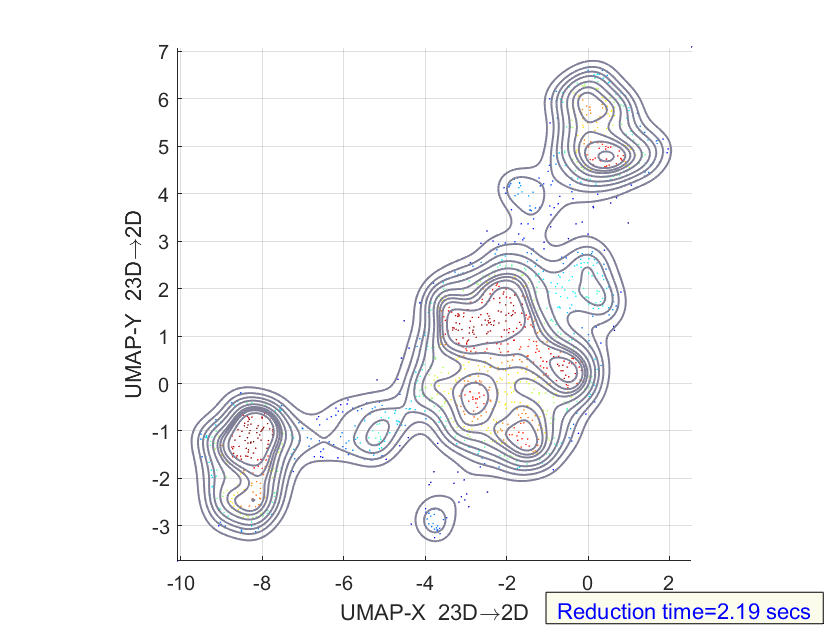

[reduction, umap, clusterIdentifiers, extras]=run_umap(X,'metric',@HammingEuclidean);

As we can see, although the three cluster here seem more marked than before but can still be more or less identified.

### Principal Components Analysis

We now use PCA to create new features to explain the output and we plot the loadings in order to understand which original features matter the most for each principal component. More than 60% of the variance is explained by the first five components. 

[loadings,score,latent,~,var] = pca(X);
var

var =    33.0605
    9.6930
    6.9764
    6.8018
    5.6143
    4.6085
    4.3563
    3.7833
    3.6552
    3.2575


We plot the first 5 PCA:

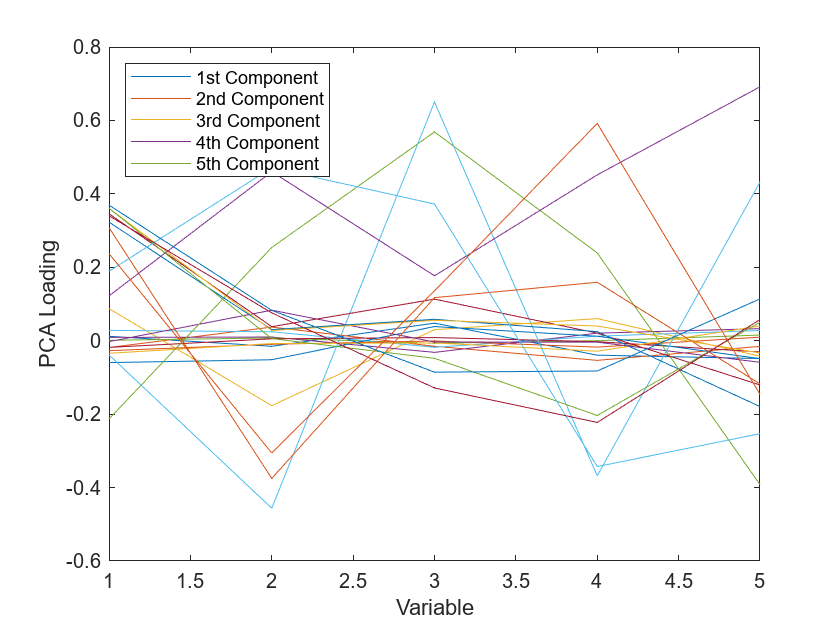

figure
plot(1:5,loadings(:,1:5),'-')
xlabel('Variable');
ylabel('PCA Loading');
legend({'1st Component' '2nd Component' '3rd Component' '4th Component' '5th Component'},'location','NW');

### K-Medoids clustering

As seen above we choose to create our cluster with the mixed Hamming-Euclidean distance. We need to take into account the fact that the medoids method doesn't always converge, so we have to run the algorithm a few times to obtain a meaningful result.

Furthermore, we tried out a few different values for the hyperparameters k to see which best fit our data.

#### K=3

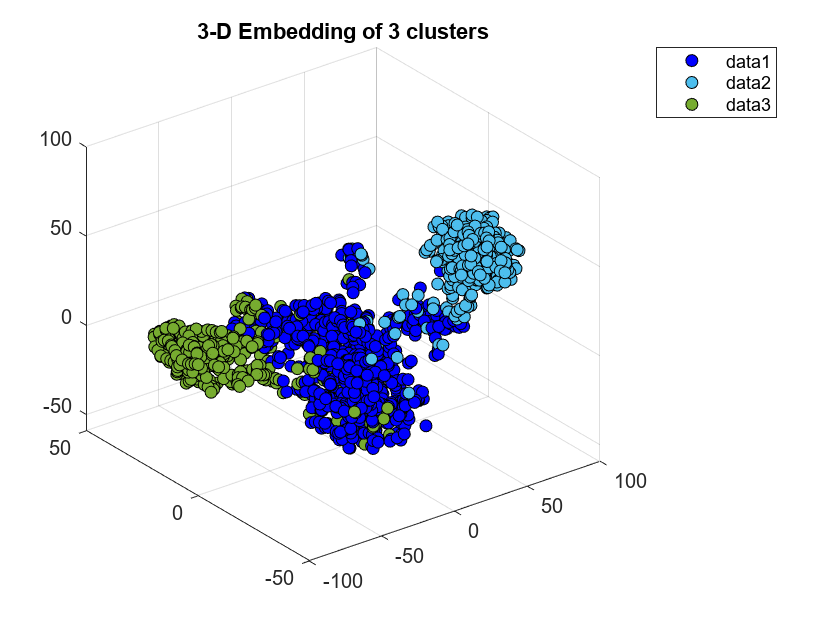

[IDX3, C3, SUMD3, D3, MIDX3, INFO3] = kmedoids(X,3,'Distance', @HammingEuclidean,'replicates',5);

figure
scatter3(Y(IDX3==1,1),Y(IDX3==1,2),Y(IDX3==1,3),...
    'MarkerEdgeColor','k',...
    'MarkerFaceColor',[0 0 1])
hold on
scatter3(Y(IDX3==2,1),Y(IDX3==2,2),Y(IDX3==2,3),...
    'MarkerEdgeColor','k',...
    'MarkerFaceColor',[0.3010 0.7450 0.9330])
scatter3(Y(IDX3==3,1),Y(IDX3==3,2),Y(IDX3==3,3),...
    'MarkerEdgeColor','k',...
    'MarkerFaceColor',[0.4660 0.6740 0.1880])
title('3-D Embedding of 3 clusters')
legend
hold off

#### K=4

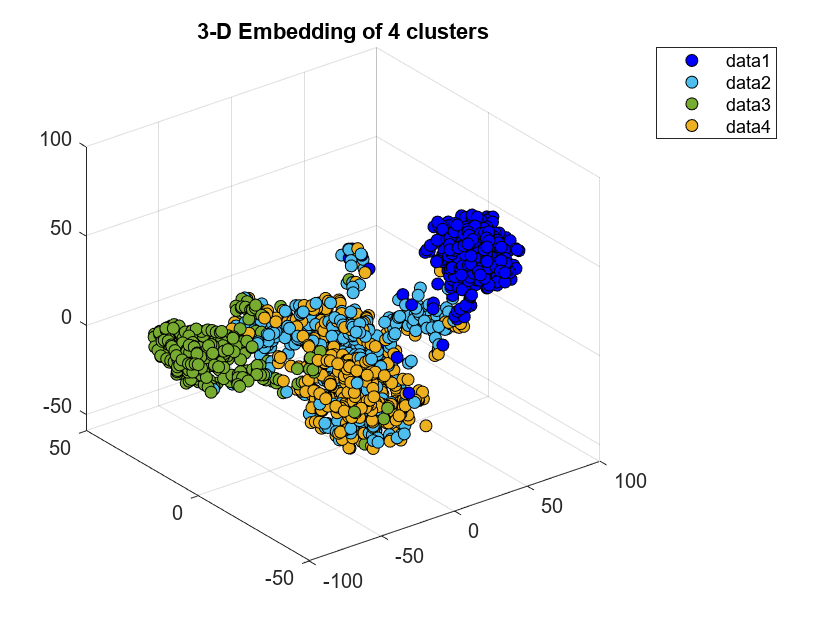

[IDX4, C4, SUMD4, D4, MIDX4, INFO4] = kmedoids(X,4,'Distance', @HammingEuclidean,'replicates',5);

figure
scatter3(Y(IDX4==1,1),Y(IDX4==1,2),Y(IDX4==1,3),...
    'MarkerEdgeColor','k',...
    'MarkerFaceColor',[0 0 1])
hold on
scatter3(Y(IDX4==2,1),Y(IDX4==2,2),Y(IDX4==2,3),...
    'MarkerEdgeColor','k',...
    'MarkerFaceColor',[0.3010 0.7450 0.9330])
scatter3(Y(IDX4==3,1),Y(IDX4==3,2),Y(IDX4==3,3),...
    'MarkerEdgeColor','k',...
    'MarkerFaceColor',[0.4660 0.6740 0.1880])
scatter3(Y(IDX4==4,1),Y(IDX4==4,2),Y(IDX4==4,3),...
    'MarkerEdgeColor','k',...
    'MarkerFaceColor',[0.9290 0.6940 0.1250])
title('3-D Embedding of 4 clusters')
hold off
legend

#### K=5

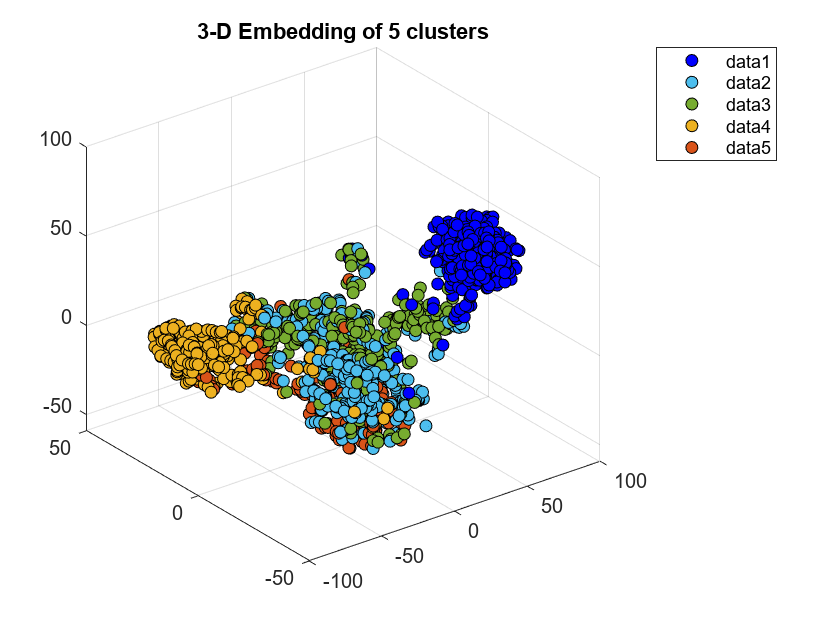

[IDX5, C5, SUMD5, D5, MIDX5, INFO5] = kmedoids(X,5,'Distance', @HammingEuclidean,'replicates',5);

figure
scatter3(Y(IDX5==1,1),Y(IDX5==1,2),Y(IDX5==1,3),...
    'MarkerEdgeColor','k',...
    'MarkerFaceColor',[0 0 1])
hold on
scatter3(Y(IDX5==2,1),Y(IDX5==2,2),Y(IDX5==2,3),...
    'MarkerEdgeColor','k',...
    'MarkerFaceColor',[0.3010 0.7450 0.9330])
scatter3(Y(IDX5==3,1),Y(IDX5==3,2),Y(IDX5==3,3),...
    'MarkerEdgeColor','k',...
    'MarkerFaceColor',[0.4660 0.6740 0.1880])
scatter3(Y(IDX5==4,1),Y(IDX5==4,2),Y(IDX5==4,3),...
    'MarkerEdgeColor','k',...
    'MarkerFaceColor',[0.9290 0.6940 0.1250])
scatter3(Y(IDX5==5,1),Y(IDX5==5,2),Y(IDX5==5,3),...
    'MarkerEdgeColor','k',...
    'MarkerFaceColor',[0.8500 0.3250 0.0980])
title('3-D Embedding of 5 clusters')
hold off
legend

#### K=6

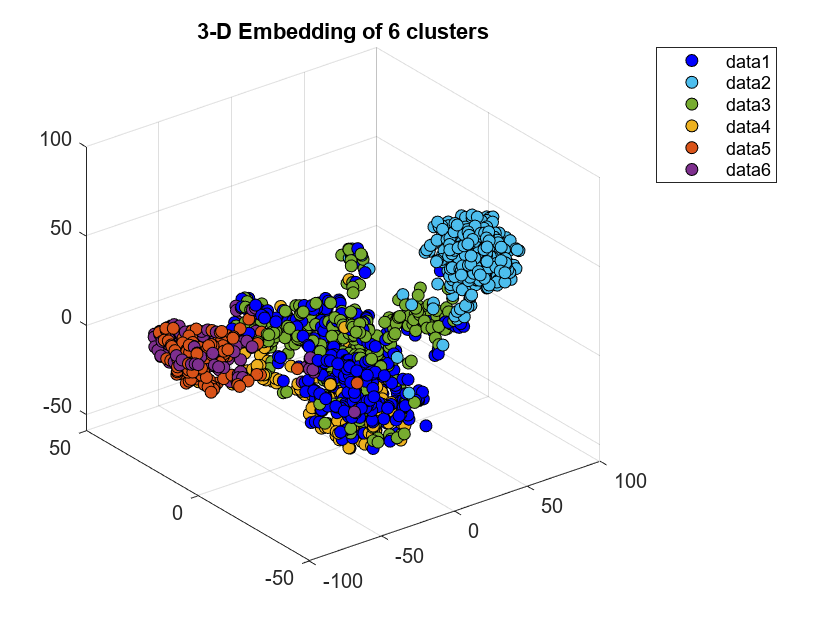

[IDX6, C6, SUMD6, D6, MIDX6, INFO6] = kmedoids(X,6,'Distance', @HammingEuclidean,'replicates',5);

figure
scatter3(Y(IDX6==1,1),Y(IDX6==1,2),Y(IDX6==1,3),...
    'MarkerEdgeColor','k',...
    'MarkerFaceColor',[0 0 1])
hold on
scatter3(Y(IDX6==2,1),Y(IDX6==2,2),Y(IDX6==2,3),...
    'MarkerEdgeColor','k',...
    'MarkerFaceColor',[0.3010 0.7450 0.9330])
scatter3(Y(IDX6==3,1),Y(IDX6==3,2),Y(IDX6==3,3),...
    'MarkerEdgeColor','k',...
    'MarkerFaceColor',[0.4660 0.6740 0.1880])
scatter3(Y(IDX6==4,1),Y(IDX6==4,2),Y(IDX6==4,3),...
    'MarkerEdgeColor','k',...
    'MarkerFaceColor',[0.9290 0.6940 0.1250])
scatter3(Y(IDX6==5,1),Y(IDX6==5,2),Y(IDX6==5,3),...
    'MarkerEdgeColor','k',...
    'MarkerFaceColor',[0.8500 0.3250 0.0980])
scatter3(Y(IDX6==6,1),Y(IDX6==6,2),Y(IDX6==6,3),...
    'MarkerEdgeColor','k',...
    'MarkerFaceColor',[0.4940 0.1840 0.5560])
title('3-D Embedding of 6 clusters')
legend
hold off

**K = 7**

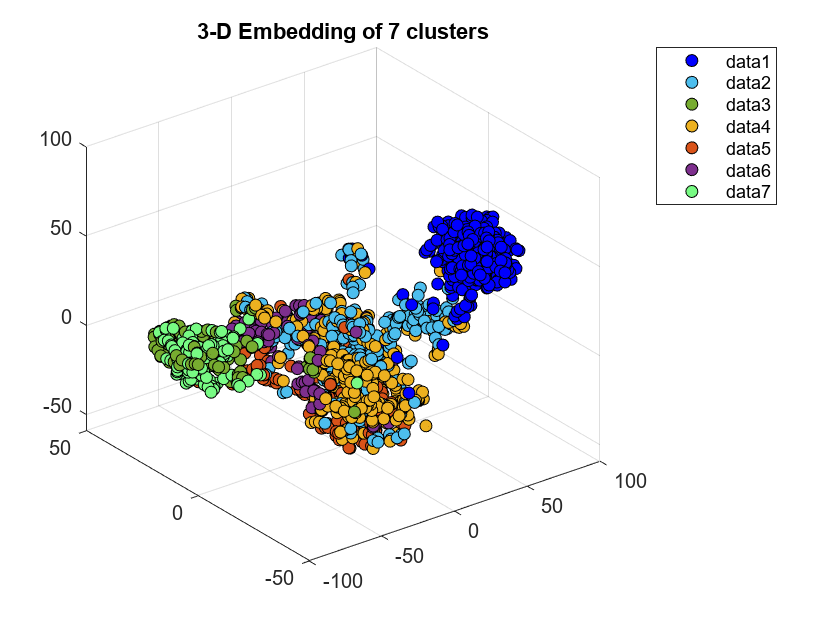

[IDX7, C7, SUMD7, D7, MIDX7, INFO7] = kmedoids(X,7,'Distance', @HammingEuclidean,'replicates',5);

figure
scatter3(Y(IDX7==1,1),Y(IDX7==1,2),Y(IDX7==1,3),...
    'MarkerEdgeColor','k',...
    'MarkerFaceColor',[0 0 1])
hold on
scatter3(Y(IDX7==2,1),Y(IDX7==2,2),Y(IDX7==2,3),...
    'MarkerEdgeColor','k',...
    'MarkerFaceColor',[0.3010 0.7450 0.9330])
scatter3(Y(IDX7==3,1),Y(IDX7==3,2),Y(IDX7==3,3),...
    'MarkerEdgeColor','k',...
    'MarkerFaceColor',[0.4660 0.6740 0.1880])
scatter3(Y(IDX7==4,1),Y(IDX7==4,2),Y(IDX7==4,3),...
    'MarkerEdgeColor','k',...
    'MarkerFaceColor',[0.9290 0.6940 0.1250])
scatter3(Y(IDX7==5,1),Y(IDX7==5,2),Y(IDX7==5,3),...
    'MarkerEdgeColor','k',...
    'MarkerFaceColor',[0.8500 0.3250 0.0980])
scatter3(Y(IDX7==6,1),Y(IDX7==6,2),Y(IDX7==6,3),...
    'MarkerEdgeColor','k',...
    'MarkerFaceColor',[0.4940 0.1840 0.5560])
scatter3(Y(IDX7==7,1),Y(IDX7==7,2),Y(IDX7==7,3),...
    'MarkerEdgeColor','k',...
    'MarkerFaceColor',[0.4700 0.9852 0.5160])
title('3-D Embedding of 7 clusters')
legend
hold off

Again, we see that the parameter K=3 seems to give the best results, while all the other number of clusters seem to cut into the central, larger cluster without creating neat separations.

### Clustering evaluation

We now pass to evaluate the clusters found above.

**Calinski-Harabasz criterion**

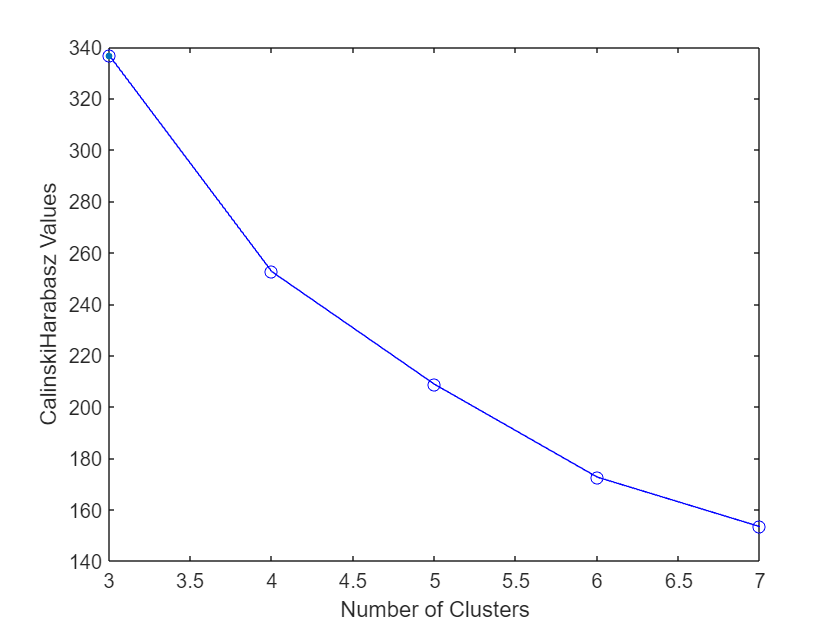

clust = [IDX3 IDX4 IDX5 IDX6 IDX7];
eva1 = evalclusters(X,clust,'CalinskiHarabasz');
figure
plot(eva1)

eva1

eva1 =   CalinskiHarabaszEvaluation with properties:

    NumObservations: 1500
         InspectedK: [3 4 5 6 7]
    CriterionValues: [336.8798 252.6278 208.7857 172.6403 153.3665]
           OptimalK: 3


Here we have to take the highest value of the plot which corresponds to the value K=3.

**Silhouette criterion** 

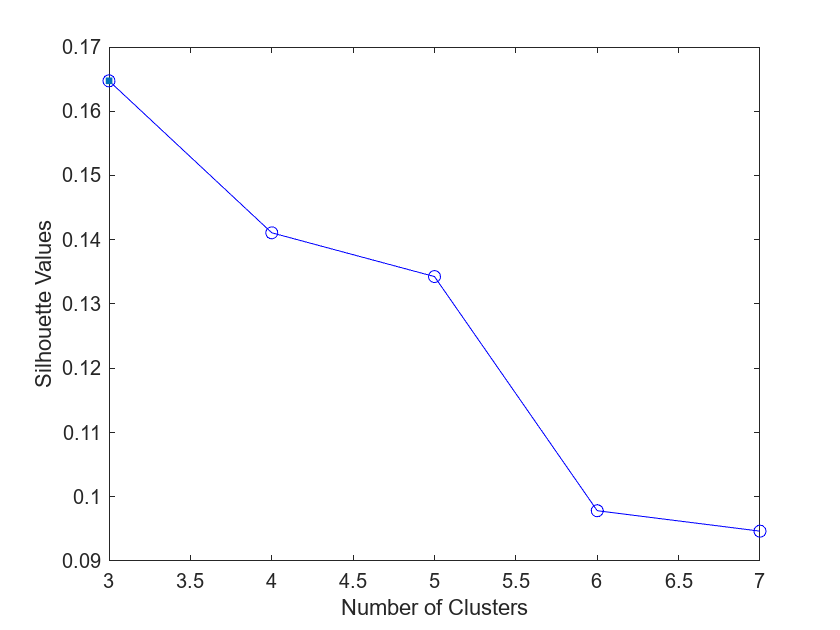

eva2 = evalclusters(X,clust,'silhouette', 'Distance', @HammingEuclidean);
figure
plot(eva2)

eva2

eva2 =   SilhouetteEvaluation with properties:

    NumObservations: 1500
         InspectedK: [3 4 5 6 7]
    CriterionValues: [0.1647 0.1411 0.1343 0.0978 0.0946]
           OptimalK: 3


Here the highest value corresponds, again, to the value K=3.

**Dunn's criterion **

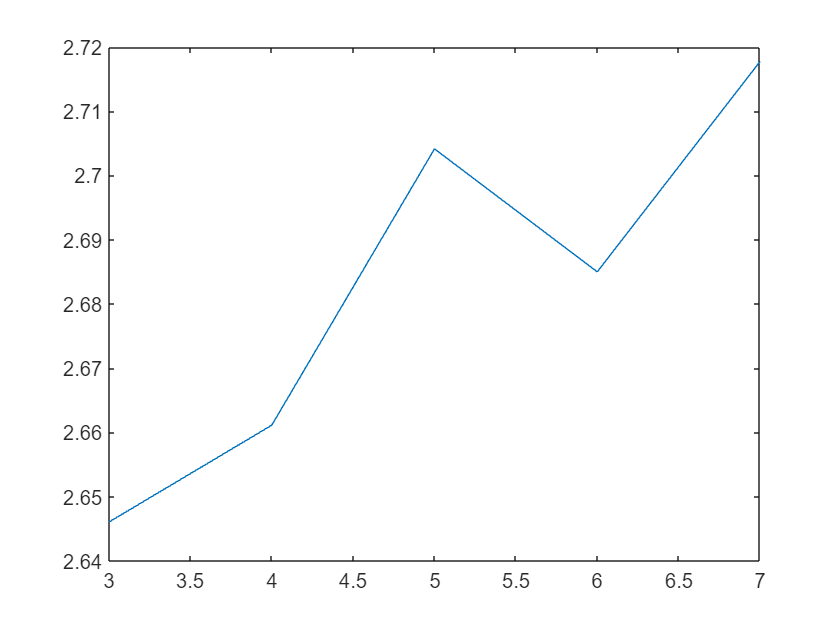

D = HammingEuclidean(X,X);
%D = pdist(X);
%D = squareform(D);
intercldist = max(D(IDX3 ~= IDX3')); % with euclidean distance 
intracldist = zeros(max(IDX3),1);
for i = 1:max(IDX3)
    intracldist(i) = mean(D(IDX3 == i, IDX3 == i), 'all');
end

Dunn3 = min(intercldist)/max(intracldist);

intercldist = max(D(IDX4 ~= IDX4')); % with euclidean distance 
intracldist = zeros(max(IDX4),1);
for i = 1:max(IDX4)
    intracldist(i) = mean(D(IDX4 == i, IDX4 == i), 'all');
end
Dunn4 = min(intercldist)/max(intracldist);

intercldist = max(D(IDX5 ~= IDX5')); % with euclidean distance 
intracldist = zeros(max(IDX5),1);
for i = 1:max(IDX5)
    intracldist(i) = mean(D(IDX5 == i, IDX5 == i), 'all');
end
Dunn5 = min(intercldist)/max(intracldist);

intercldist = max(D(IDX6 ~= IDX6')); % with euclidean distance 
intracldist = zeros(max(IDX6),1);
for i = 1:max(IDX6)
    intracldist(i) = mean(D(IDX6 == i, IDX6 == i), 'all');
end
Dunn6 = min(intercldist)/max(intracldist);

intercldist = max(D(IDX7 ~= IDX7')); % with euclidean distance 
intracldist = zeros(max(IDX7),1);
for i = 1:max(IDX7)
    intracldist(i) = mean(D(IDX7 == i, IDX7 == i), 'all');
end
Dunn7 = min(intercldist)/max(intracldist);

Dunn = [Dunn3, Dunn4, Dunn5, Dunn6, Dunn7];
plot(3:7,Dunn)

In summary although Dunn's criterion seems to be somewhat inconclusive the other two methods point strongly in the direction of 3 clusters as being the best option.

**Spectral clustering**

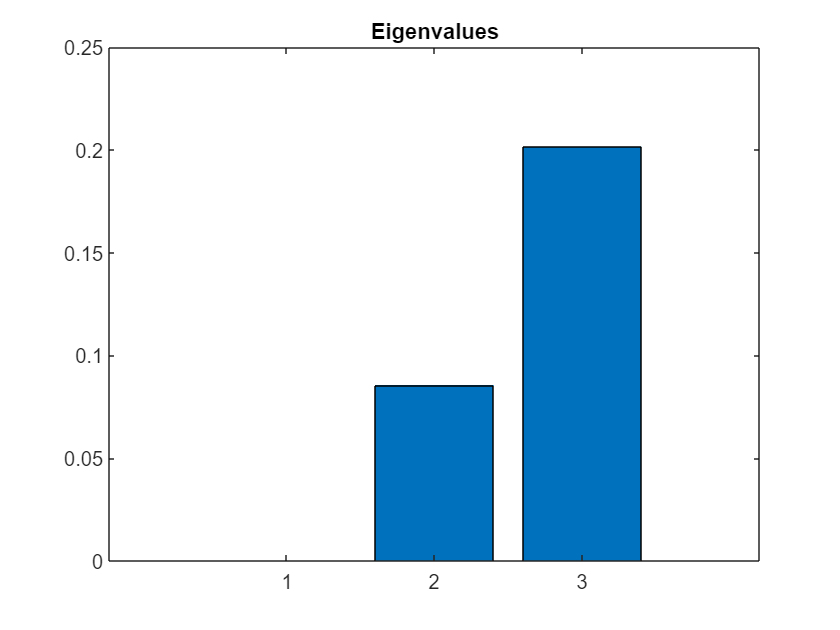

Distance = HammingEuclidean(X,X);
Similarity = exp(-Distance.^2); % kernel transformation
issymmetric(Similarity); % check symmetry
nCluster = 3;
[SpectralIdx, V, D] = spectralcluster(Similarity,nCluster,'Distance','precomputed','LaplacianNormalization','symmetric');
figure
bar(D)
title('Eigenvalues')

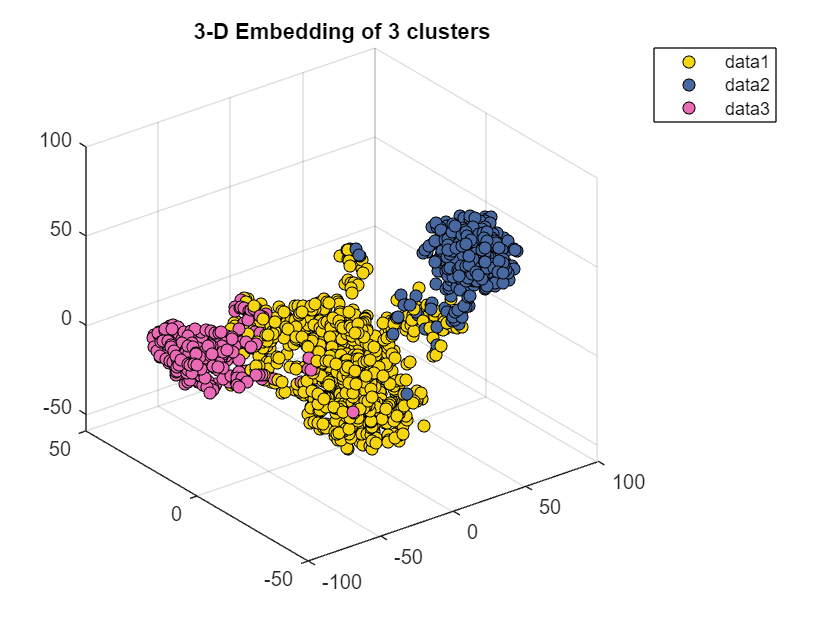

figure
for i = 1:nCluster
    scatter3(Y(SpectralIdx==i,1),Y(SpectralIdx==i,2),Y(SpectralIdx==i,3),...
        'MarkerEdgeColor','k',...
        'MarkerFaceColor',[rand() rand() rand()])  % random colors
    hold on
end
title('3-D Embedding of 3 clusters')
hold off
legend

The spectral analysis too seems to point in the direction of 3 clusters.

## **Inspecting clusters**

Let's focus now on business interpretation of the dataset. We try to individuate personas characterised by particular features. We build a scatterplot observing age, gender, income, financial education, investment and savings:

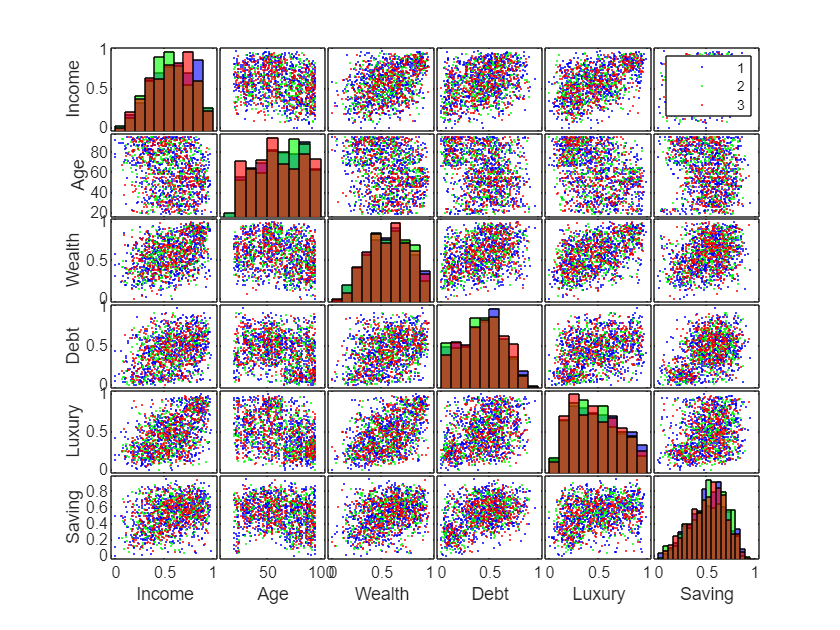

Data4Plot = [BankClients.Income BankClients.Age  BankClients.Wealth BankClients.Debt BankClients.Luxury  BankClients.Saving];
xnames = {'Income', 'Age', 'Wealth', 'Debt', 'Luxury', 'Saving'};
gplotmatrix(Data4Plot(1:1500,:),[],IDX3, [],[],[],[],'grpbars', xnames)

We chose 3 clusters and we explore avarage statistics for the unscaled Data:

% add the cluster column to the data and take the random select at the
% beginning
Data_grp = Data(randRows',:);
Data_grp.("Cluster") = IDX3;
ClusterCardinality = grpstats(Data_grp,"Cluster").("GroupCount");
ClusterCardinality = ClusterCardinality/sum(ClusterCardinality)

ClusterCardinality =     0.5273
    0.2233
    0.2493


ClusterMedian = grpstats(Data_grp(:,N),"Cluster","median")

ClusterMedian = 3×14 table
         Cluster    GroupCount    median_Age    median_FamilySize    median_Income    median_Wealth    median_Debt    median_FinEdu    median_ESG    median_Digital    median_BankFriend    median_LifeStyle    median_Luxury    median_Saving
         _______    __________    __________    _________________    _____________    _____________    ___________    _____________    __________    ______________    _________________    ________________    _____________    _____________

    1